# Supervised Learning - Week 2 / Part 2

## Feature Engineering

For many practical applications, choosing the right features is critical for making the algorithm work well.

**Question:** How can we choose the right features?

Let's revisit the predicting the house prices problem for feature engineering. Let's assume that we have two features for each house.

- $x_1$: width of the lot size of the plots of land that the house is built on (also known as frontage)

- $x_2$: depth of the lot size of the plots of land that the house is built on

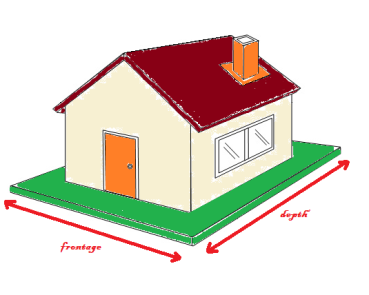

Given that $x_1$ and $x_2$, you can build a model as follows:


$$f_{\mathbf{w},b}(\mathbf{x}) = w_1x_1 + w_2x_2 + b$$


There is also a more efficient way how you can build your model using the area of the rectangle that the house is built on

You can have the intuition that the area of the land is more predictive of the price than frontage and depth as separate features. Therefore you might invent a feature ($x_3$), where the new feature is equivalent to $x_3 = x_1 \times x_2$.

With this new feature you can have the following model:


$$f_{\mathbf{w},b}(\mathbf{x}) = w_1x_1 + w_2x_2 + w_3x_3 + b$$


So that the model can choose the parameters $w_1$, $w_2$, and $w_3$ depending on whether the data shows frontage, depth or the area. It turns out the $x_3$ is the most important feature for predicting the price of a house.

This is an example of **feature enginnering**, 

Using your intuition to design new features, by transforming or combining original features in order to make it easier for the learning algorithm to make accurate predictions. Therefore, rather than just taking the features that you happened to have, sometimes by defining new features, you might be able to get a much better model.

Note: It is important to note that feature engineering could also allow you to fit not only straight lines but curves (non-linear functions) to your data.

## Polynomial Regression

So far we've been fitting straight lines to our data - Let's take the ideas of multi-variable linear regression and feature engineering to come up with a new algorithm called polynomial regression, which will let us to fit curves (non-linear functions) to our data.

Let's say we have the housing data, where the feature in x-axis is the size of the house (in sq. feet) and y-axis is the price of the house. The polynomial dataset created as follows:

- Load "HousePricesDataset"

- $x_{\text{new}} = 0.5x + 0.02x^2$ and $y_{\text{new}} = y$.

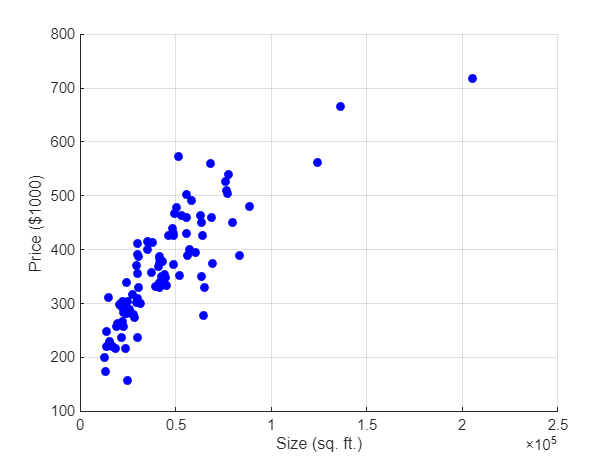

figure;
dataset = importdata('house_prices_dataset.txt');
X = dataset(:,1); % size in sq. ft.
X = 0.5.*X + 0.02.*X.^2;
X_norm = X./max(X);
y = dataset(:,end); % prices
y_norm = y./max(y);
scatter(X,y,'blue','filled')
xlabel('Size (sq. ft.)')
ylabel('Price ($1000)')
grid on

1) As can be seen above, the datapoints are not following an exact straight line since the increase in the price is less compared to the increase in the size. Hence, we can infer that a straight line won't fit the data we have wery well. Therefore, we might want to fit a curve, such as a quadratic function such as $f_{\mathbf{w},b} = w_1x + w_2x^2 + b$, which includes the size ($x$) and also squared size ($x^2$). 

2) You might also realized that the $f_{\mathbf{w},b} = w_1x + w_2x^2 + b$ quadratic function is not making sense since the quadratic function will eventually come down (price decreases as size increases), which would not projecting the real life behaviour.

3) So that, we can choose a cubic function such as $f_{\mathbf{w},b} = w_1x + w_2x^2 + w_3x^3 + b$, which not only have $x^2$ but also $x^3$. This model might produce a better curve, which is a somewhat better fit to the data since the prices are constantly increasing as the size increases.

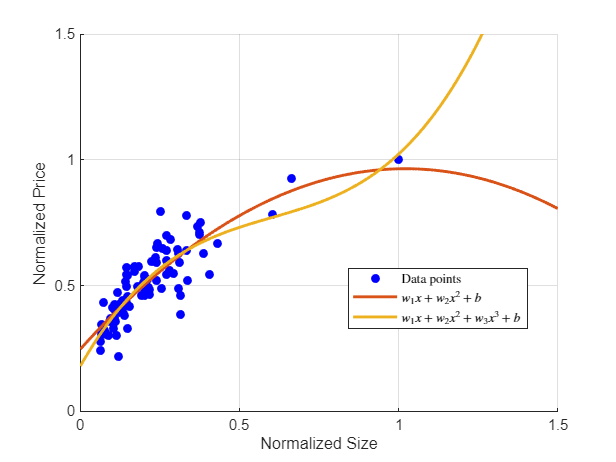

figure;
scatter(X_norm,y_norm,'blue','filled')
xlabel('Normalized Size')
ylabel('Normalized Price')

hold on
XX = 0:0.01:1.5;
yy = -0.6887.*XX.^2 + 1.4058.*XX + 0.2474;
plot(XX,yy,'LineWidth',2)

yyy = 1.6973.*XX.^3 - 3.0669.*XX.^2 + 2.2123.*XX + 0.1801;
plot(XX,yyy,'LineWidth',2)
hold off
legend('Data points','$w_1x+w_2x^2+b$','$w_1x+w_2x^2+w_3x^3+b$',...
    'Interpreter','latex','Location','best');
ylim([0 1.5])
grid on

4) It is important to note that if you create new features like $x^2$ and/or $x^3$, the feature scaling becomes increasingly important. Let's assume the range of the size feature is in $[1 ~~~ 1000]$ sq. ft., which would mean that the range of the $x^2$ and $x^3$ becomes $[1 ~~ 10^6]$ and $[1 ~~~ 10^9]$, respectively. Thus, the squared and cubed sizes will take on very different ranges compared to the original feature $x$. If you are using gradient descent (GD) it is important to apply feature scaling to get your features into the comparable ranges of values.

5) As a final example let's see how wide range of choices of features we have to use, an alternative to use size squared and cubed is to use the square root of $x$. Therefore your model will look like as follows:

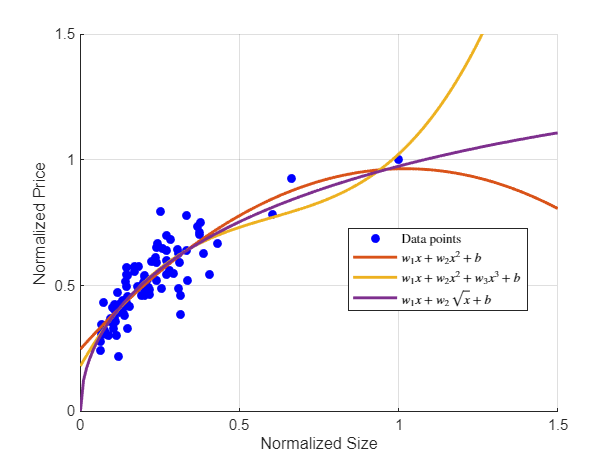

figure;
scatter(X_norm,y_norm,'blue','filled')
xlabel('Normalized Size')
ylabel('Normalized Price')

hold on
XX = 0:0.01:1.5;
yy = -0.6887.*XX.^2 + 1.4058.*XX + 0.2474;
plot(XX,yy,'LineWidth',2)

yyy = 1.6973.*XX.^3 - 3.0669.*XX.^2 + 2.2123.*XX + 0.1801;
plot(XX,yyy,'LineWidth',2)

sqy = -0.3168.*XX + 1.2957.*sqrt(XX) - 0.0042;
plot(XX,sqy,'LineWidth',2)

hold off
legend('Data points','$w_1x+w_2x^2+b$','$w_1x+w_2x^2+w_3x^3+b$',...
    '$w_1x+w_2\sqrt x+b$','Interpreter','latex','Location','best');
ylim([0 1.5])
grid on

As can be seen from the above plot, the square root function becomes a bit less steep as $x$ increases. but it doesn't get completely flatten out and it certainly never ever comes back down since $\frac{\text{d}f(x)}{\text{d}x}  = \frac{\text{d}\left(\sqrt x\right)}{\text{d}x} = \frac{1}{2\sqrt x}$, where $\lim_{x\rightarrow\infty} \frac{1}{2\sqrt x} =  0$. Therefore, the size squared could be another choice of features that might work well for this dataset.

- **Question:** How should we decide what features to use?

In the upcoming files of this series we will see how we can choose different features and different models and we will have a process for measuring how well these different models perform to help us to decide which features to include.

## Lab: Practical Implementation of Polynomial Regression

In this lab we will learn how to implement feature engineering and polynomical regression, which will allow us to use the process of linear regression to fit very complicated (non-linear) functions.

### Overview

Linear regression provides us means of building models in the form: $f_{\mathbf{w},b} = w_0x_0 + w_1x_1 + \cdots + w_{n-1}x_{n-1} + b$    (1),

What if our features/data are non-linear or are combinations of features? For instance, the housing prices do not tend to follow a linear trend with living area but penalize a very smal or very large houses. How can we use the linear regression algoruthm/structure/machinery to fit a non-linear curve? Here, algorithm/structure/machinery means to modify the parameters $\mathbf{w}$ and $b$ in (1) to fit the training data. However, no amount of adjusting of $\mathbf{w}$ and $b$ in (1) will be able to fit to a non-linear curve.

### Polynomial Features

Let's use what we learnt so far to fit a non-linear curve. We will start with a simple quadratic function: $y = x^2 + 1$

% Create the synthetic dataset
X = (0:1:19).'; % feature vector
y = X.^2 + 1; % target vector

% Run batch gradient descent (BGD) algorithm
alpha = 1e-2; % learning rate
[J_vec,w_vec,b_vec] = hGeneralizedBatchGradientDescent(X,y,alpha,initMethod="zero",J_stop=1e-2,iter_stop=1e4,verbose=true,verboseFreq=1000);

Iteration #0 | Cost: 1657.5633
Iteration #1000 | Cost: 440.9539
Iteration #2000 | Cost: 438.9097
Iteration #3000 | Cost: 438.9
Iteration #4000 | Cost: 438.9
Iteration #5000 | Cost: 438.9
Iteration #6000 | Cost: 438.9
Iteration #7000 | Cost: 438.9
Iteration #8000 | Cost: 438.9
Iteration #9000 | Cost: 438.9
* BGD stopped: max number of iterations (9999)
Parameters found using BGD w: [ 19.0000 ], b: -56.0000


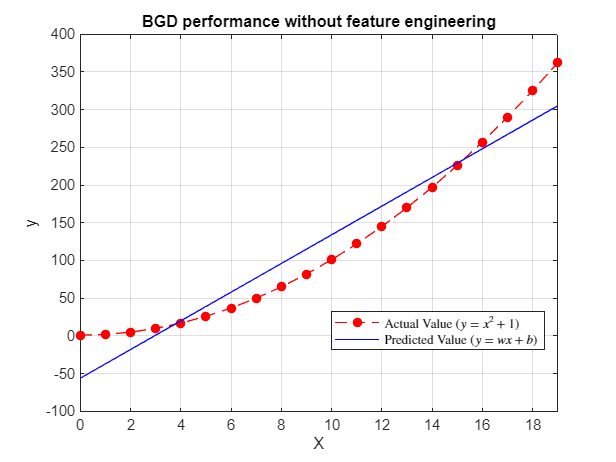

% Plot the targets and predictions
figure;
plot(X,y,'ro--','MarkerFaceColor','r')
xlim([min(X) max(X)])
xlabel('X')
ylabel('y')
grid on
title('BGD performance without feature engineering')
hold on
plot(X,w_vec(end).*X + b_vec(end),'b')
legend({'Actual Value ($y=x^2 + 1$)','Predicted Value ($y=wx + b$)'},'Location','best','Interpreter','latex')
hold off

As can be seen from the above figure we haven't got a great fit, which was expected since our model is linear and our data is non-linear. What is needed as a model here is something like $y = wx^2 + b$ or a **polynomial feature**. To achieve this, we need to modify (feature engineering) the input data features:

% Create the synthetic dataset
X = (0:1:19).'; % feature vector
y = X.^2 + 1; % target vector

% Engineer the features
X_hat = X.^2;

% Run batch gradient descent (BGD) algorithm
alpha = 1e-5; % learning rate
[J_vec,w_vec,b_vec] = hGeneralizedBatchGradientDescent(X_hat,y,alpha,initMethod="zero",J_stop=0,iter_stop=1e4,verbose=true,verboseFreq=1000);

Iteration #0 | Cost: 7329.2181
Iteration #1000 | Cost: 0.22484
Iteration #2000 | Cost: 0.22279
Iteration #3000 | Cost: 0.22076
Iteration #4000 | Cost: 0.21875
Iteration #5000 | Cost: 0.21676
Iteration #6000 | Cost: 0.21478
Iteration #7000 | Cost: 0.21282
Iteration #8000 | Cost: 0.21088
Iteration #9000 | Cost: 0.20896
* BGD stopped: max number of iterations (9999)
Parameters found using BGD w: [ 1.0042 ], b: 0.0490


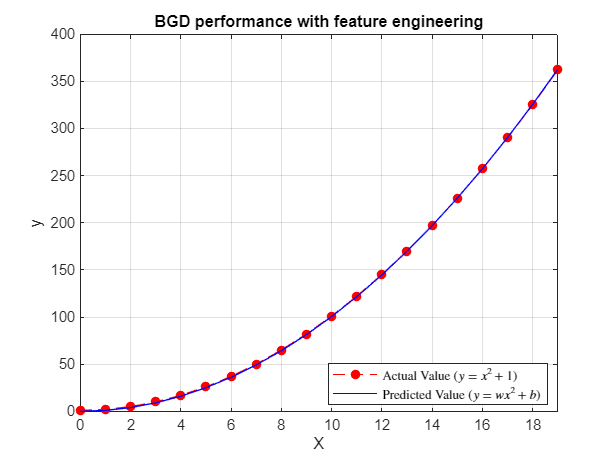

% Plot the targets and predictions
figure;
plot(X,y,'ro--','MarkerFaceColor','r')
xlim([min(X) max(X)])
xlabel('X')
ylabel('y')
grid on
title('BGD performance with feature engineering')
hold on
plot(X,w_vec(end).*X_hat + b_vec(end),'b')
legend({'Actual Value ($y=x^2 + 1$)','Predicted Value ($y=wx^2 + b$)'},'Location','best','Interpreter','latex')
hold off

As we can see from the figure above, it is almost a perfect fit. Note that the final parameter values are slightly off from the actual values; $w = 1.004$ and $b = 0.049$. If we ran the BGD longer it would yield a better result.

### Selecting Features

In the example above we had the prior knowledge of we had to select the $x^2$ term. However, this might not always be the case and we might not know which features with which transformation is required. One solution might be adding variety of potential features to try and find the most useful combination. For instance, we could try the following model: $y = w_0x_0 + w_1x_1^2 + w_2x_2^3 + b$.

% Create the synthetic dataset
X = (0:1:19).'; % feature vector
y = X.^2; % target vector

% Engineer the features
X_hat = [X X.^2 X.^3];

% Run batch gradient descent (BGD) algorithm
alpha = 1e-7; % learning rate
[J_vec,w_vec,b_vec] = hGeneralizedBatchGradientDescent(X_hat,y,alpha,initMethod="zero",J_stop=0,iter_stop=1e4,verbose=true,verboseFreq=1000);

Iteration #0 | Cost: 1140.2924
Iteration #1000 | Cost: 328.5395
Iteration #2000 | Cost: 280.4434
Iteration #3000 | Cost: 239.3886
Iteration #4000 | Cost: 204.3443
Iteration #5000 | Cost: 174.4304
Iteration #6000 | Cost: 148.896
Iteration #7000 | Cost: 127.0998
Iteration #8000 | Cost: 108.4946
Iteration #9000 | Cost: 92.6132
* BGD stopped: max number of iterations (9999)
Parameters found using BGD w: [ 0.0824 ], w: [ 0.5355 ], w: [ 0.0275 ], b: 0.0106


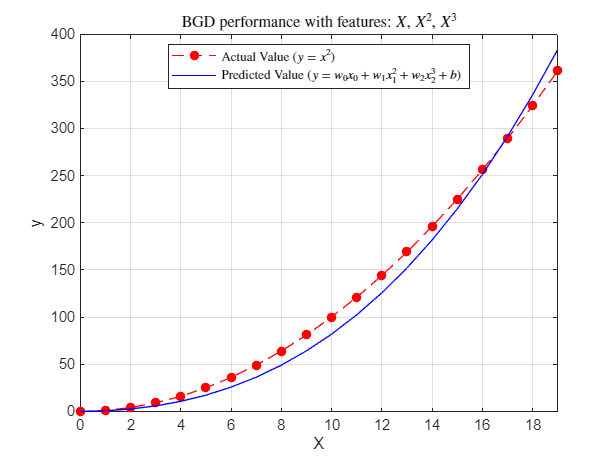

% Plot the targets and predictions
figure;
plot(X,y,'ro--','MarkerFaceColor','r')
xlim([min(X) max(X)])
xlabel('X')
ylabel('y')
grid on
title('BGD performance with features: $X$, $X^2$, $X^3$','Interpreter','latex')
hold on
plot(X,X_hat*w_vec(end,:).' + b_vec(end),'b')
legend({'Actual Value ($y=x^2$)','Predicted Value ($y=w_0x_0 + w_1x_1^2 + w_2x_2^3 + b$)'},'Location','best','Interpreter','latex')
hold off

As can be seen from the final results that the model obtained after fitting/training becomes: $y = 0.082x + 0.535x^2 + 0.028x^3 + 0.032$, whete BGD emphasized that the data has the best fit to the $x^2$ by increasing $w_1$ term relative to $w_0$, $w_2$ and $b$. If we were to run the algoritm for longer, it would increase the emphasis on $x^2$ and reduce the other parameters values close to 0 even more. Therefore we can say that:

- **Gradient descent is picking the 'correct' features for us by emphasizing its associated parameter**

- **Less weight value implies less important/correct feature, when the weight becomes very close to zero (or zero), the associated feature is not useful in fitting the model to the data.**

- **As can be seen from th example above, after fitting the data, the weight associated with **$x^2$** became much larger as it is the most useful feature in fitting our synthetic data.**

### An Alternative View

In the examples given above the polynomial features were chosen based on the how well they match the target data. In other words, we are still using linear regression parameters; $w$ and $b$, to fit the data with new synthetic features; such as $X$, $X^2$, $X^3$ and so on. Note that the best features will be linear relative to the target. Let's investigate this with an example:

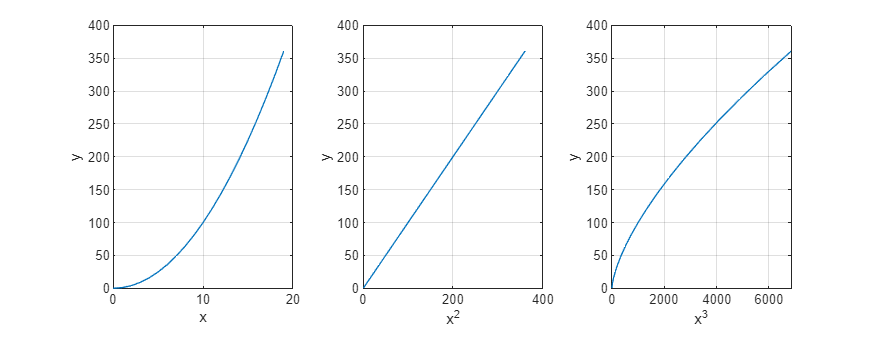

% Create the target data
x = (0:1:19).'; % features
y = x.^2; % targets

% Engineer the features
X = [x x.^2 x.^3]; % added engineered feature
X_featureLabel = ["x","x^2","x^3"];

% Plot the individual features
f = figure;
tiledlayout(1,numel(X_featureLabel));
for i = 1:numel(X_featureLabel)
    nexttile
    plot(X(:,i),y)
    xlabel(X_featureLabel(i))
    ylabel("y")
    grid on
end
f.Position = [0 0 900 350];

We can clearly see from the above plots that the $x^2$ feature linearly maps against the target values $y$. Therefore, linear regression algorithm could easily generate a mode using the $x^2$ feature.

## Scaling Features

If a dataset has features with significantly different scales, the gradient descent algorithm's speed could be improved simply by applying feature scaling. In the example above, the features $x$, $x^2$, and $x^3$naturally have different scales. Let's apply Z-normalization to the all three features.

% Create the target data
x = (0:1:19).'; % features
X = [x x.^2 x.^3]; % engineered features
X_norm = zScoreNormalizeFeatures(X); % input normalization
fprintf('Peak-to-peak range for each column in raw X: [ %g %g %g ]\n',max(X)-min(X))

Peak-to-peak range for each column in raw X: [ 19 361 6859 ]


fprintf('Peak-to-peak range for each column in z-score normalized X: [ %.3f %.3f %.3f ]\n',max(X_norm)-min(X_norm))

Peak-to-peak range for each column in z-score normalized X: [ 3.295 3.181 3.283 ]


Let's try BGD algortihm again with more aggresive (larger) value of the learning rate after the normalization.

% Create the target data
x = (0:1:19).'; % features
y = x.^2; % targets
X = [x x.^2 x.^3]; % engineered features
X_norm = zScoreNormalizeFeatures(X); % input normalization

% Run batch gradient descent (BGD) algorithm
alpha = 1e-1; % learning rate
[J_vec,w_vec,b_vec] = hGeneralizedBatchGradientDescent(X_norm,y,alpha,initMethod="zero",J_stop=0,iter_stop=1e5,verbose=true,verboseFreq=1e4,accelaration=true);

Iteration #0 | Cost: 9421.4668
Iteration #10000 | Cost: 0.39094
Iteration #20000 | Cost: 0.027839
Iteration #30000 | Cost: 0.0019824
Iteration #40000 | Cost: 0.00014117
Iteration #50000 | Cost: 1.0053e-05
Iteration #60000 | Cost: 7.1585e-07
Iteration #70000 | Cost: 5.0976e-08
Iteration #80000 | Cost: 3.63e-09
Iteration #90000 | Cost: 2.585e-10
* BGD stopped: max number of iterations (99999)
Parameters found using BGD w: [ 0.0001 ], w: [ 113.4946 ], w: [ 0.0001 ], b: 123.5000


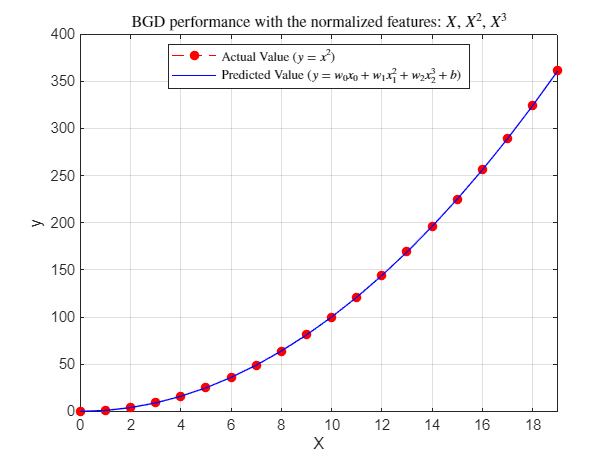

% Plot the targets and predictions
figure;
plot(x,y,'ro--','MarkerFaceColor','r')
xlim([min(x) max(x)])
xlabel('X')
ylabel('y')
grid on
title('BGD performance with the normalized features: $X$, $X^2$, $X^3$','Interpreter','latex')
hold on
plot(x,X_norm*w_vec(end,:).' + b_vec(end),'b')
legend({'Actual Value ($y=x^2$)','Predicted Value ($y=w_0x_0 + w_1x_1^2 + w_2x_2^3 + b$)'},'Location','best','Interpreter','latex')
hold off

- Note from the above figure that feature scaling helps to converge faster. Compared to the previous plot, the predicted values match more closely even when the learning rate is significantly larger.

- Note again that the second weight, which represents the feature $x^2$, is the most emphasized. The gradient descent algorithm emphasized the $x^2$ term and discarded the $x$ and $x^3$ terms.

## Higher Order (Complex) Polynomial Functions

By using the trick above, we can model even more complex non-linear functions just by BGD algortihm for linear regression.

% Create the target data
x = (0:1:19).'; % features
y = cos(x/2); % targets
X = [x x.^2 x.^3 x.^4 x.^5 x.^6 x.^7 x.^8 x.^9 x.^10 x.^11 x.^12 x.^13]; % engineered features
X_norm = zScoreNormalizeFeatures(X); % input normalization

% Run batch gradient descent (BGD) algorithm
alpha = 1e-1; % learning rate
[J_vec,w_vec,b_vec] = hGeneralizedBatchGradientDescent(X_norm,y,alpha,initMethod="zero",J_stop=0,iter_stop=1e6,verbose=true,verboseFreq=1e5,accelaration=true);

Iteration #0 | Cost: 0.22019
Iteration #100000 | Cost: 0.017007
Iteration #200000 | Cost: 0.01276
Iteration #300000 | Cost: 0.0097303
Iteration #400000 | Cost: 0.0075644
Iteration #500000 | Cost: 0.0060141
Iteration #600000 | Cost: 0.0049025
Iteration #700000 | Cost: 0.0041035
Iteration #800000 | Cost: 0.0035273
Iteration #900000 | Cost: 0.0031099
* BGD stopped: max number of iterations (999999)
Parameters found using BGD w: [ -1.3357 ], w: [ -10.0023 ], w: [ 24.7780 ], w: [ 5.9617 ], w: [ -12.4859 ], w: [ -16.2628 ], w: [ -9.5081 ], w: [ 0.5919 ], w: [ 8.7030 ], w: [ 11.9413 ], w: [ 9.2710 ], w: [ 0.7890 ], w: [ -12.8175 ], b: -0.0073


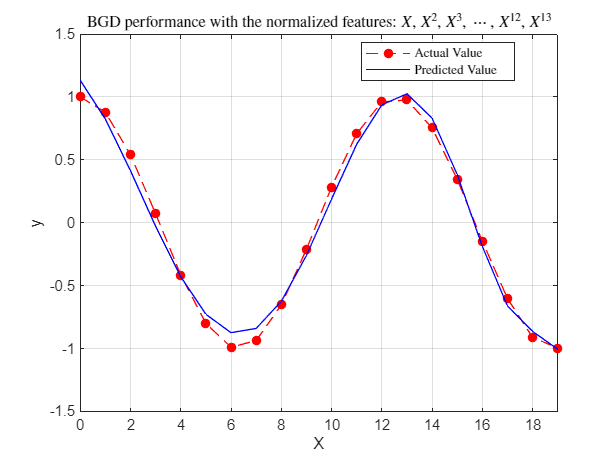

% Plot the targets and predictions
figure;
plot(x,y,'ro--','MarkerFaceColor','r')
xlim([min(x) max(x)])
xlabel('X')
ylabel('y')
grid on
title('BGD performance with the normalized features: $X$, $X^2$, $X^3$, $\cdots$, $X^{12}$, $X^{13}$','Interpreter','latex')
hold on
plot(x,X_norm*w_vec(end,:).' + b_vec(end),'b')
legend({'Actual Value','Predicted Value'},'Location','best','Interpreter','latex')
hold off

- We learned how a Batch Gradient Descent (BGD)-based linear regression algorithm can model non-linear functions, including those with high-order non-linearity, through the use of feature engineering.

- We learned that feature scaling aids BGD in achieving faster convergence and reduces the estimation error between the target and predicted values.

## Local Functions

function output = zScoreNormalizeFeatures(input)
    mu = mean(input);
    sigma = sqrt(mean((input-mu).^2));
    output = (input-mu)./sigma;
end